clc
clear
a = -0.9421;
b = 82.7231;
c = 14.2306;
p = -3.7808;
q = 4.9952;
r = 57.1120;
h = 0.1;

## 1. Discretization of a state-space model

a) find matrices of discrete-time model 

Ac = [0 1 0 0;
      b 0 0 a;
      0 0 0 1;
      q 0 0 p];
Bc = [0;c;0;r];
% Two ways to get discrete system
% Method 1: c2d()
[F,G]=c2d(Ac,Bc,h)

F =     1.4421    0.1143         0   -0.0045
    9.4370    1.4421         0   -0.0908
    0.0237    0.0008    1.0000    0.0833
    0.4814    0.0237         0    0.6845


G =     0.0677
    1.3715
    0.2530
    4.7660


% Method 2: from scrach
newM = [Ac, Bc;
        zeros(1,4), 0];
dM = expm(newM*h)

dM =     1.4421    0.1143         0   -0.0045    0.0677
    9.4370    1.4421         0   -0.0908    1.3715
    0.0237    0.0008    1.0000    0.0833    0.2530
    0.4814    0.0237         0    0.6845    4.7660
         0         0         0         0    1.0000


Ad = dM(1:4,1:4)

Ad =     1.4421    0.1143         0   -0.0045
    9.4370    1.4421         0   -0.0908
    0.0237    0.0008    1.0000    0.0833
    0.4814    0.0237         0    0.6845


Bd = dM(1:4,5)

Bd =     0.0677
    1.3715
    0.2530
    4.7660


b) continuous system has input delay of 0.8h, find Aa, Ba, Ca

Ac,Bc->Aht,Bht

Ac,Bc->Atau, Btau

tau=0.8*h;
tempM = expm(newM*(h-tau));
Aht = tempM(1:4,1:4);
Bht = tempM(1:4,5);

tempM = expm(newM*tau);
Atau = tempM(1:4,1:4);
Btau = tempM(1:4,5);

A = Aht*Atau;
B1 = Aht*Btau;
B2 = Bht;

Aa = [A, B1;
      zeros(1,4), 0]

Aa =     1.4421    0.1143         0   -0.0045    0.0649
    9.4370    1.4421         0   -0.0908    1.0958
    0.0237    0.0008    1.0000    0.0833    0.2419
    0.4814    0.0237         0    0.6845    3.6657
         0         0         0         0         0


Ba = [B2;1]

Ba =     0.0028
    0.2757
    0.0111
    1.1002
    1.0000


eig(Aa)

ans =     1.0000
    2.4781
    0.4008
    0.6899
         0


eig(Ad)

ans =     1.0000
    2.4781
    0.4008
    0.6899


## 2. Dynamic Programming solution of the LQ problem

h=0.01;
[A,B]=c2d(Ac,Bc,h);
A=[1.0041 0.01 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9626];
B = [0.0007;0.1398;0.0028;0.5605];
C = [1 0 0 0;0 0 1 0];
Q = eye(4);
Pf = 10*eye(4);
R=1;

a) Use DP to find the shortest N that makes system (5) with u(k) = Kx(k), asymptoically stable

N = 5;
while true
    P = cell([1,N+1]); % P(0)~P(5)
    K = cell([1,N]); % u(0)~u(4)
    P{N+1} = Pf;
    for k=N+1:-1:2
        K{k-1} = -inv(R+B'*P{k}*B)*B'*P{k}*A;
        P{k-1} = Q + A'*P{k}*A + A'*P{k}*B*K{k-1};
    end
    Ak = A+B*K{1};
    e = eig(Ak);
    if max(e)<1
        str = ["iterated: ", N "times"];
        disp(str)
        disp(K{1})
        break
    else
        e_last = e(1);
        N = N + 1;        
    end
end

    "iterated: "    "33"    "times"



  -46.0887   -5.2202    0.0161    0.4012



b)  Find the stationary solution$P_\infty

$

[P_inf,~,~] = idare(A,B,Q,R,[],[])

P_inf = 1.0e+04 *

    4.8430    0.5290   -0.1035   -0.1146
    0.5290    0.0584   -0.0114   -0.0126
   -0.1035   -0.0114    0.0125    0.0027
   -0.1146   -0.0126    0.0027    0.0030


N = 5;
while true
    P = cell([1,N+1]); % P(0)~P(5)
    K = cell([1,N]); % u(0)~u(4)
    P{N+1} = Pf;
    for k=N+1:-1:2
        K{k-1} = -inv(R+B'*P{k}*B)*B'*P{k}*A;
        P{k-1} = Q + A'*P{k}*A + A'*P{k}*B*K{k-1};
    end
    Ak = A+B*K{1};
    e = eig(Ak);
    if norm(P{2}-P{1})<0.1
        str = ["iterated: ", N "times"];
        disp(str)
        P{1}
        break
    else
        e_last = e(1);
        N = N + 1;        
    end
end

    "iterated: "    "426"    "times"



ans = 1.0e+04 *

    4.8425    0.5289   -0.1034   -0.1146
    0.5289    0.0584   -0.0114   -0.0126
   -0.1034   -0.0114    0.0125    0.0027
   -0.1146   -0.0126    0.0027    0.0030


c) Consider the stationary matrix P∞ from (b) as the new terminal cost gain Pf , see (6). Provide the new control gain and find the shortest N that makes the system (5) asymptotically stable with u(k) = Kx(k); explain in the report the difference with the N found in question (a).

N = 1;
Pf = P_inf;
while true
    P = cell([1,N+1]); % P(0)~P(5)
    K = cell([1,N]); % u(0)~u(4)
    P{N+1} = Pf;
    for k=N+1:-1:2
        K{k-1} = -inv(R+B'*P{k}*B)*B'*P{k}*A;
        P{k-1} = Q + A'*P{k}*A + A'*P{k}*B*K{k-1};
    end
    Ak = A+B*K{1};
    e = eig(Ak);
    if max(e)<1
        str = ["iterated: ", N "times"];
        disp(str)
        break
    else
        e_last = e(1);
        N = N + 1;        
    end
end

    "iterated: "    "1"    "times"



## 3. Batch solution of the LQ problem

Find the shortest N that makes the system (5) stable

h=0.01;
[A,B]=c2d(Ac,Bc,h)

A =     1.0041    0.0100         0   -0.0000
    0.8281    1.0041         0   -0.0093
    0.0002    0.0000    1.0000    0.0098
    0.0491    0.0002         0    0.9629


B =     0.0007
    0.1398
    0.0028
    0.5605


A=[1.0041 0.01 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9626];
B = [0.0007;0.1398;0.0028;0.5605];
C = [1 0 0 0;0 0 1 0];
Q = eye(4);
Pf = 10*eye(4);
R=1;

N = 3;
n = 4;
p = 1;
while true 
    Qbar = blkdiag(kron(eye(N-1), Q), Pf);
    Rbar = kron(eye(N),R);
    Gamma = zeros(n*N, p*N);
    Omega = zeros(n*N, n);
    for i = 0:N-1
       Gamma = Gamma + kron(diag(ones(N-i, 1), -i), A^i*B);
       Omega = Omega + [zeros(i*n,n); A^(i+1); zeros((N-1-i)*n, n)];
    end
    Kb = -inv((Gamma'*Qbar*Gamma + Rbar))*Gamma'*Qbar*Omega;    
    Ak = A+B*Kb(1,:);
    e = eig(Ak);
    if(max(e)<1)
        str = ["iterated: ", N "times"];
        disp(str)
        Kb(1,:)
        break
    else
        N = N + 1;
    end
end

    "iterated: "    "33"    "times"



ans =   -46.0887   -5.2202    0.0161    0.4012


## 4. Receding horizon control

A=[1.0041 0.01 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9626];
B = [0.0007;0.1398;0.0028;0.5605];
Q = eye(4);
Pf = 10*eye(4);
x0 = [pi/38 0 0 0]';
n = 4;
p = 1;
steps = 200;

R = 1;
N = 40;
[x1,u1] = simulateRHC(A,B,N,Q,R,Pf,n,p,x0,steps);
R = 1;
N = 80;
[x2,u2] = simulateRHC(A,B,N,Q,R,Pf,n,p,x0,steps);
R = 0.1;
N = 40;
[x3,u3] = simulateRHC(A,B,N,Q,R,Pf,n,p,x0,steps);
R = 0.1;
N = 80;
[x4,u4] = simulateRHC(A,B,N,Q,R,Pf,n,p,x0,steps);

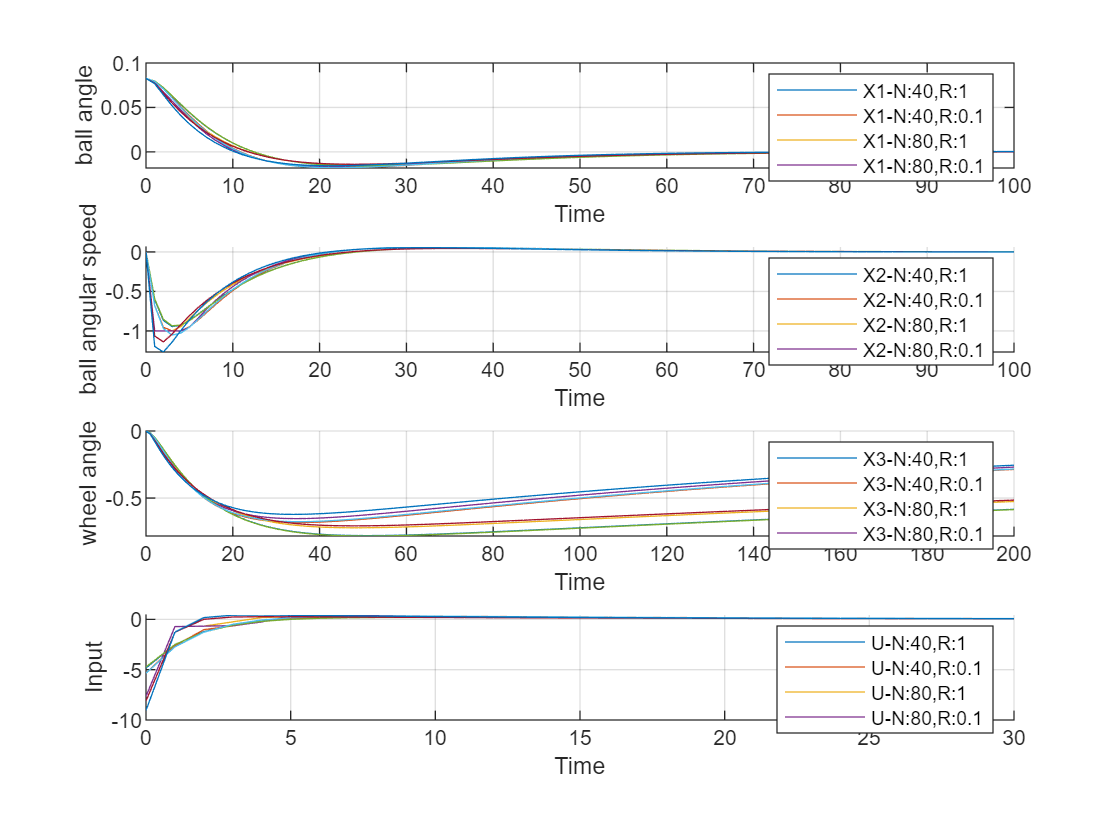

subplot(4,1,1)
plot(0:100, x1(1,1:100+1))
hold on
grid on
plot(0:100, x2(1,1:100+1))
plot(0:100, x3(1,1:100+1))
plot(0:100, x4(1,1:100+1))
legend("X1-N:40,R:1","X1-N:40,R:0.1","X1-N:80,R:1","X1-N:80,R:0.1")
xlabel("Time")
ylabel("ball angle")
subplot(4,1,2)
hold on 
grid on
plot(0:100, x1(2,1:100+1))
plot(0:100, x2(2,1:100+1))
plot(0:100, x3(2,1:100+1))
plot(0:100, x4(2,1:100+1))
legend("X2-N:40,R:1","X2-N:40,R:0.1","X2-N:80,R:1","X2-N:80,R:0.1")
xlabel("Time")
ylabel("ball angular speed")
subplot(4,1,3)
hold on
grid on
plot(0:200, x1(3,1:200+1))
plot(0:200, x2(3,1:200+1))
plot(0:200, x3(3,1:200+1))
plot(0:200, x4(3,1:200+1))
legend("X3-N:40,R:1","X3-N:40,R:0.1","X3-N:80,R:1","X3-N:80,R:0.1")
xlabel("Time")
ylabel("wheel angle")
subplot(4,1,4)
hold on
grid on
plot(0:30, u1(1,1:30+1))
plot(0:30, u2(1,1:30+1))
plot(0:30, u3(1,1:30+1))
plot(0:30, u4(1,1:30+1))
legend("U-N:40,R:1","U-N:40,R:0.1","U-N:80,R:1","U-N:80,R:0.1")
xlabel("Time")
ylabel("Input")

## 5.Constrained receding horizon control

A=[1.0041 0.01 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9626];
B = [0.0007;0.1398;0.0028;0.5605];
C = [1 0 0 0;0 0 1 0];
D  = 0;
Q = eye(4);
Pf = 10*eye(4);
n  = length(A);
p  = size(B,2);            
x0 = [pi/38 0 0 0]'; % initial state

x2_max = 1;
u_max = 8;

steps = 200;

R  = 1;
N  = 40;
F      = kron([eye(N); zeros(N)], [0 1 0 0;0 -1 0 0]);
G      = kron([zeros(N); eye(N)], [1;-1]);
h      = [x2_max*ones(2*N,1); u_max*ones(2*N,1)];
[x1,u1] = simulateCRHC(A,B,N,Q,R,Pf,n,p,x0,steps,F,G,h);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


R  = 1;
N  = 80; 
F      = kron([eye(N); zeros(N)], [0 1 0 0;0 -1 0 0]);
G      = kron([zeros(N); eye(N)], [1;-1]);
h      = [x2_max*ones(2*N,1); u_max*ones(2*N,1)];
[x2,u2] = simulateCRHC(A,B,N,Q,R,Pf,n,p,x0,steps,F,G,h);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


R  = 0.1;
N  = 40;
F      = kron([eye(N); zeros(N)], [0 1 0 0;0 -1 0 0]);
G      = kron([zeros(N); eye(N)], [1;-1]);
h      = [x2_max*ones(2*N,1); u_max*ones(2*N,1)];
[x3,u3] = simulateCRHC(A,B,N,Q,R,Pf,n,p,x0,steps,F,G,h);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


R  = 0.1;
N  = 80;
F      = kron([eye(N); zeros(N)], [0 1 0 0;0 -1 0 0]);
G      = kron([zeros(N); eye(N)], [1;-1]);
h      = [x2_max*ones(2*N,1); u_max*ones(2*N,1)];
[x4,u4] = simulateCRHC(A,B,N,Q,R,Pf,n,p,x0,steps,F,G,h);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

x4 =     0.0827    0.0777    0.0675    0.0573    0.0471    0.0371    0.0279    0.0199    0.0131    0.0072    0.0023   -0.0019   -0.0054   -0.0082   -0.0106   -0.0124   -0.0139   -0.0150   -0.0159   -0.0165   -0.0168   -0.0170   -0.0170   -0.0169   -0.0167   -0.0164   -0.0160   -0.0156   -0.0151   -0.0146   -0.0140   -0.0134   -0.0129   -0.0123   -0.0117   -0.0111   -0.0106   -0.0100   -0.0095   -0.0089   -0.0084   -0.0079   -0.0074   -0.0070   -0.0066   -0.0061   -0.0057   -0.0054   -0.0050   -0.0046
         0   -1.0000   -1.0000   -1.0000   -1.0000   -0.9554   -0.8389   -0.7215   -0.6154   -0.5214   -0.4388   -0.3664   -0.3030   -0.2477   -0.1996   -0.1578   -0.1217   -0.0905   -0.0637   -0.0408   -0.0214   -0.0049    0.0089    0.0204    0.0299    0.0376    0.0438    0.0486    0.0523    0.0551    0.0569    0.0580    0.0586    0.0585    0.0581    0.0573    0.0562    0.0548    0.0533    0.0516    0.0498    0.0479    0.0460    0.0440    0.0420    0.0400    0.0381    0.0361    0.0342    

u4 =    -7.6428   -0.7154   -0.6709   -0.6241   -0.2558    0.3188    0.4002    0.3903    0.3650    0.3387    0.3138    0.2908    0.2695    0.2499    0.2317    0.2151    0.1997    0.1855    0.1724    0.1603    0.1492    0.1390    0.1296    0.1209    0.1129    0.1055    0.0987    0.0925    0.0867    0.0814    0.0765    0.0720    0.0678    0.0640    0.0605    0.0572    0.0542    0.0515    0.0489    0.0466    0.0444    0.0424    0.0406    0.0389    0.0373    0.0358    0.0345    0.0333    0.0321    0.0311


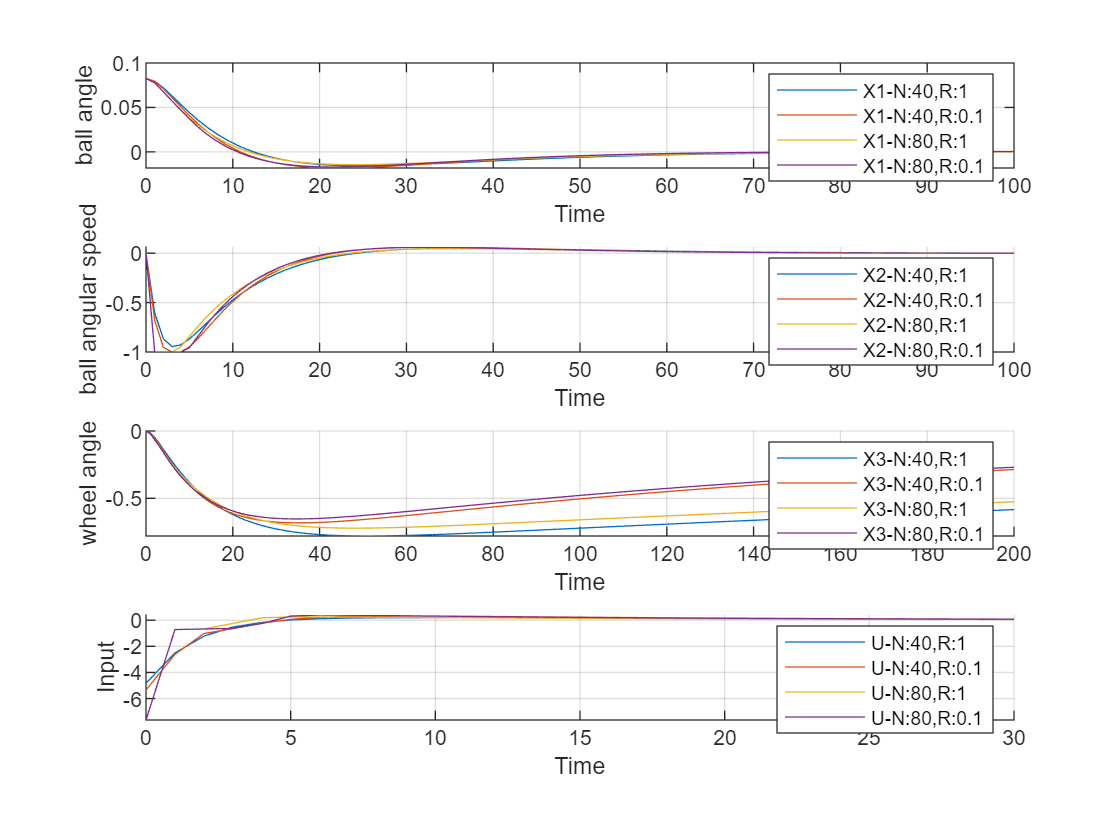

figure
subplot(4,1,1)
plot(0:100, x1(1,1:100+1))
hold on
grid on
plot(0:100, x2(1,1:100+1))
plot(0:100, x3(1,1:100+1))
plot(0:100, x4(1,1:100+1))
legend("X1-N:40,R:1","X1-N:40,R:0.1","X1-N:80,R:1","X1-N:80,R:0.1")
xlabel("Time")
ylabel("ball angle")
subplot(4,1,2)
hold on 
grid on
plot(0:100, x1(2,1:100+1))
plot(0:100, x2(2,1:100+1))
plot(0:100, x3(2,1:100+1))
plot(0:100, x4(2,1:100+1))
legend("X2-N:40,R:1","X2-N:40,R:0.1","X2-N:80,R:1","X2-N:80,R:0.1")
xlabel("Time")
ylabel("ball angular speed")
subplot(4,1,3)
hold on
grid on
plot(0:200, x1(3,1:200+1))
plot(0:200, x2(3,1:200+1))
plot(0:200, x3(3,1:200+1))
plot(0:200, x4(3,1:200+1))
legend("X3-N:40,R:1","X3-N:40,R:0.1","X3-N:80,R:1","X3-N:80,R:0.1")
xlabel("Time")
ylabel("wheel angle")
subplot(4,1,4)
hold on
grid on
plot(0:30, u1(1,1:30+1))
plot(0:30, u2(1,1:30+1))
plot(0:30, u3(1,1:30+1))
plot(0:30, u4(1,1:30+1))
legend("U-N:40,R:1","U-N:40,R:0.1","U-N:80,R:1","U-N:80,R:0.1")
xlabel("Time")
ylabel("Input")

function Kb = batchRHC(A,B,N,Q,R,Pf,n,p)
    Qbar = blkdiag(kron(eye(N-1),Q),Pf);
    Rbar = kron(eye(N),R);
    Gamma = zeros(n*N, p*N);
    Omega = zeros(n*N, n);
    for i = 0:N-1
       Gamma = Gamma + kron(diag(ones(N-i, 1), -i), A^i*B);
       Omega = Omega + [zeros(i*n,n); A^(i+1); zeros((N-1-i)*n, n)];
    end
    Kb = -inv((Gamma'*Qbar*Gamma + Rbar))*Gamma'*Qbar*Omega;  
end

function [x, u] = simulateRHC(A,B,N,Q,R,Pf,n,p,x0,steps)
    x = zeros(n,steps);
    u = zeros(p,steps);
    x(:,1) = x0;
    for itr = 1:steps
        Kb = batchRHC(A,B,N,Q,R,Pf,n,p); % [N*n]
        K = Kb(1,:); %[1*n]
        u(itr) = K*x(:,itr); %[1*1]
        x(:, itr+1) = A*x(:,itr)+B*u(itr);
    end
end

function [x,u] = simulateCRHC(A,B,N,Q,R,Pf,n,p,x0,steps,F,G,h)
    x = zeros(n,steps);
    u = zeros(p,steps);
    x(:,1) = x0;
    for itr = 1:steps
        [Z,~] = CRHC(A,B,N,Q,R,Pf,F,G,h,x(:,itr),n);
        x(:, itr+1) = Z(1:n); % take the first 4 states of the first time k state
        u(itr)   =  Z(n*N+1); % take the n*N+1 (th) u
    end
end